# **PARCIAL 4**

`Gerson Alexander Sanchez Brito`

`Juan Sebastian Avila Diaz`

## **Baton Thrown into Air**

[https://youtu.be/FOmJnEkHWX4](https://youtu.be/FOmJnEkHWX4)

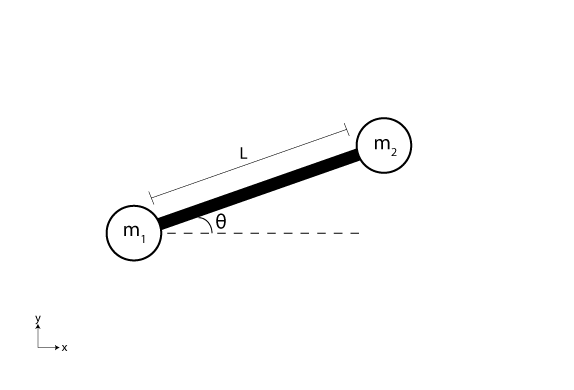

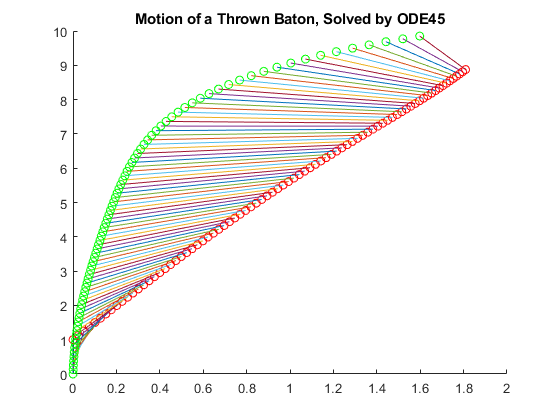

clc,clear all,close all
syms x Dx DDx y Dy DDy th Dth DDth
syms L g
syms q1 q2 q3 q4 q5 q6 Dq2 Dq4 Dq6 

%P.m1 = 0.1;
%P.m2 = 0.1;
P.L = 1;
P.g = 9.8;
tspan = linspace(0,0.5,80); %vector de puntos
y0 = [0; 4; 1; 20; -pi/2; -3.9]; %condiciones iniciales
opts = odeset('Mass',@(t,q) mass(t,q,P)); %
[t,q] = ode45(@(t,q) f(t,q,P),tspan,y0,opts);

figure
title('Motion of a Thrown Baton, Solved by ODE45');
%axis([0 10 0 20])
hold on
for j = 1:length(t)
   theta = q(j,5);
   X = q(j,1);
   Y = q(j,3);
   xvals = [X X+P.L*cos(theta)];
   yvals = [Y Y+P.L*sin(theta)];
   plot(xvals,yvals,xvals(1),yvals(1),'ro',xvals(2),yvals(2),'go')
end
hold off

### MATRIZ DE MASA

function M = mass(t,q,P)
% Extract parameters
%m1 = P.m1;
%m2 = P.m2;
L = P.L;
g = P.g;

% Mass matrix function
M = zeros(6,6);
M(1,1) = 1; %Dq1
M(2,2) = 15*exp(-(q(1)*q(3)*q(5)*t)/100) - (3*exp((q(1)*q(3)*q(5)*t)/100)*(-2))/4 ; %Dq2(1)
M(2,6) = -(3*exp((q(1)*q(3)*q(5)*t)/100)*(2*L*sin(q(5))))/4; %Dq6(1)
M(3,3) = 1;%Dq3
M(4,4) = 15*exp(-(q(1)*q(3)*q(5)*t)/100) - (3*exp((q(1)*q(3)*q(5)*t)/100)*(- 2))/4; %Dq4(2)
M(4,6) = (3*exp((q(1)*q(3)*q(5)*t)/100)*(2*L*cos(q(5))))/4 ; %Dq6(2)
M(5,5) = 1; %Dq5
M(6,2) = (3*L*exp((q(1)*q(3)*q(5)*t)/100)*sin(q(5))*(L*cos(q(5))*q(6)^2 - 1))/2 - (3*L^2*q(6)^2*exp((q(1)*q(3)*q(5)*t)/100)*cos(q(5))*sin(q(5)))/2; %Dq2(3)
M(6,4) = - (3*L*exp((q(1)*q(3)*q(5)*t)/100)*cos(q(5))*(- 1))/2;%Dq4(3)
M(6,6) = (3*L*exp((q(1)*q(3)*q(5)*t)/100)*cos(q(5))*(L*cos(q(5))))/2 + (3*L*exp((q(1)*q(3)*q(5)*t)/100)*sin(q(5))*( L*sin(q(5))))/2;%Dq6(3)
end

function dydt = f(t,q,P)
% Extract parameters
%m1 = P.m1;
%m2 = P.m2;
L = P.L;
g = P.g;

% Equation to solve
dydt = [q(2)
        15*q(2)*exp(-(q(1)*q(3)*q(5)*t)/100)*((q(1)*q(3)*q(5))/100 + (q(1)*q(3)*q(6)*t)/100 + (q(1)*q(4)*q(5)*t)/100 + (q(2)*q(3)*q(5)*t)/100) - (3*exp((q(1)*q(3)*q(5)*t)/100)*(2*q(2) - 2*L*q(6)*sin(q(5)))*((q(1)*q(3)*q(5))/100 + (q(1)*q(3)*q(6)*t)/100 + (q(1)*q(4)*q(5)*t)/100 + (q(2)*q(3)*q(5)*t)/100))/4 + (3*L*q(6)^2*exp((q(1)*q(3)*q(5)*t)/100)*cos(q(5)))/2 + (3*g*q(3)^2*q(5)*t*exp(-(q(1)*q(3)*q(5)*t)/100))/20 - (3*q(2)^2*q(3)*q(5)*t*exp(-(q(1)*q(3)*q(5)*t)/100))/40 - (3*q(3)*q(4)^2*q(5)*t*exp(-(q(1)*q(3)*q(5)*t)/100))/40 + (3*q(3)*q(5)*t*exp((q(1)*q(3)*q(5)*t)/100)*(q(4) + L*q(6)*cos(q(5)))^2)/400 + (3*q(3)*q(5)*t*exp((q(1)*q(3)*q(5)*t)/100)*(q(2) - L*q(6)*sin(q(5)))^2)/400 - (3*g*q(3)*q(5)*t*exp((q(1)*q(3)*q(5)*t)/100)*(q(3) + L*sin(q(5))))/200 - 2*q(2)
        q(4)
        15*q(4)*exp(-(q(1)*q(3)*q(5)*t)/100)*((q(1)*q(3)*q(5))/100 + (q(1)*q(3)*q(6)*t)/100 + (q(1)*q(4)*q(5)*t)/100 + (q(2)*q(3)*q(5)*t)/100) - (3*g*exp((q(1)*q(3)*q(5)*t)/100))/2 - (3*exp((q(1)*q(3)*q(5)*t)/100)*(2*q(4) + 2*L*q(6)*cos(q(5)))*((q(1)*q(3)*q(5))/100 + (q(1)*q(3)*q(6)*t)/100 + (q(1)*q(4)*q(5)*t)/100 + (q(2)*q(3)*q(5)*t)/100))/4 - 15*g*exp(-(q(1)*q(3)*q(5)*t)/100) + (3*L*q(6)^2*exp((q(1)*q(3)*q(5)*t)/100)*sin(q(5)))/2 - (3*q(1)*q(2)^2*q(5)*t*exp(-(q(1)*q(3)*q(5)*t)/100))/40 - (3*q(1)*q(4)^2*q(5)*t*exp(-(q(1)*q(3)*q(5)*t)/100))/40 + (3*q(1)*q(5)*t*exp((q(1)*q(3)*q(5)*t)/100)*(q(4) + L*q(6)*cos(q(5)))^2)/400 + (3*q(1)*q(5)*t*exp((q(1)*q(3)*q(5)*t)/100)*(q(2) - L*q(6)*sin(q(5)))^2)/400 - (3*g*q(1)*q(5)*t*exp((q(1)*q(3)*q(5)*t)/100)*(q(3) + L*sin(q(5))))/200 + (3*g*q(1)*q(3)*q(5)*t*exp(-(q(1)*q(3)*q(5)*t)/100))/20 - 2*q(4)
        q(6)
        (3*g*q(1)*q(3)^2*t*exp(-(q(1)*q(3)*q(5)*t)/100))/20 - (3*L*g*exp((q(1)*q(3)*q(5)*t)/100)*cos(q(5)))/2 - (3*q(1)*q(2)^2*q(3)*t*exp(-(q(1)*q(3)*q(5)*t)/100))/40 - (3*q(1)*q(3)*q(4)^2*t*exp(-(q(1)*q(3)*q(5)*t)/100))/40 - (3*L*exp((q(1)*q(3)*q(5)*t)/100)*cos(q(5))*(q(4) + L*q(6)*cos(q(5)))*((q(1)*q(3)*q(5))/100 + (q(1)*q(3)*q(6)*t)/100 + (q(1)*q(4)*q(5)*t)/100 + (q(2)*q(3)*q(5)*t)/100))/2 + (3*q(1)*q(3)*t*exp((q(1)*q(3)*q(5)*t)/100)*(q(4) + L*q(6)*cos(q(5)))^2)/400 + (3*q(1)*q(3)*t*exp((q(1)*q(3)*q(5)*t)/100)*(q(2) - L*q(6)*sin(q(5)))^2)/400 + (3*L*exp((q(1)*q(3)*q(5)*t)/100)*sin(q(5))*(q(2) - L*q(6)*sin(q(5)))*((q(1)*q(3)*q(5))/100 + (q(1)*q(3)*q(6)*t)/100 + (q(1)*q(4)*q(5)*t)/100 + (q(2)*q(3)*q(5)*t)/100))/2 - (3*g*q(1)*q(3)*t*exp((q(1)*q(3)*q(5)*t)/100)*(q(3) + L*sin(q(5))))/200 - 2*q(6)];
end